## 模拟退火（SA）算法在随机仿真优化中的应用（与KN算法对比）

            本文在Alrefaei(1999)的基础上，展示了一种基于模拟退火的的仿真优化方法，并将其与KN算法进行对比。

### SA算法相对于KN算法的特点

随机优化语境下的SA算法，本质上是一种能够根据历史采样，实时更新采样额度分配的序列优化算法

直觉上SA算法具有以下两大特点，将可能使得SA算法具有较好的表现

- 采样分配：SA算法对历史表现更好的参数分配更多的采样数量，好钢用在刀刃上

- 样本利用：SA算法在选取最优参数时使用所有采样进行评判，充分利用所有采样

- 全可行域：KN算法随着迭代的进行会逐渐排出表现较差的参数，直至最后只留有一个参数。而SA算法不会随着迭代的进行而缩减参数的可行域。这使得最优值不太可能由于随机性而被排除

### SA算法过程

step0: initialization

            随机在可行域中选择一个可行参数x，设定初始温度T。

step1: epoch

            从可行参数x出发，在邻域中随机选择一个候选参数z。比较两个参数的表现f_x & f_y：

            【在**确定性优化**中往往使用函数值】

                    若z的表现优于x，则前进到z的位置，这与贪婪算法相同；

                    但若z的表现差于z，SA仍然以一定的概率P前进到z。

step2: cooling

            降低温度T。

            回到step2，直至满足结束条件。

step3: optimal

            结束迭代后根据一定的规则选择最优参数。

           【在**确定性优化**中往往选择最后收敛到的参数作为最优参数】

### SA算法的特点

- 爬坡性：step1中的概率P与参数表现f_x,f_z，以及温度T有关。两者差距越小，温度T越高，则SA算法以越大的概率接受 “哪怕更差的参数z”。这赋予了SA算法“爬坡”的特点（在最小化问题的语境下）。

- 收敛性：当迭代次数非常多，温度T非常低的时候，SA算法几乎不可能接受较差的候选参数z，此时SA算法几乎等同与贪婪算法，从而保证了其收敛性。

### SA算法在随机优化中的拓展

基础SA算法：基础的SA算法是一种针对于确定性函数的随机优化算法。本文在以下两点对算法进行拓展到随机优化：

- step1 epoch中，参数 x & z 表现（ f_x & f_z ）的衡量：使用蒙特卡洛采样，并累计所有迭代中的样本，以算术平均作为参数表现。

- step3 optimal中，最优参数的选择：使用被访问次数最多的参数，或者累积仿真值最优的参数

Alrefaei(1999)证明了，在满足一定条件时，上述拓展算法在随机优化问题中将收敛到最优参数。

### SA算法

以下展示了SA算法，

为了与KN算法做比较，迭代次数设为5000次（这是KN算法的平均迭代次数）

  基础设置

clear
rng(1)
global N X x_index V cumulative_sum samplesize f_hat

假设我们需要对以下仿真过程的参数进行优化，

parameter = 1

parameter = 1

simulation(parameter) %仿真过程函数的定义在文末，与HW4相同

ans = 0.5490

此处示例的仿真过程使用了HW4的仿真过程，以便与KN算法进行对比，即方差与均值成正比的正态分布

按照HW4，可选参数为有限离散值1～10

由于采用全集作为探索邻域，因此参数的排布顺序不影响退火算法的搜索

N = 10;
delta = 0.1; %indifference-zone parameter
X = 1:10;


参数设置

V = repelem(0,N);
cumulative_sum = repelem(0,N);
samplesize = repelem(0,N);

Step 0： initialization

tic %计时

x_index = randsample(N,1);
V(x_index) = V(x_index)+1;

Step 1: epoch

epoch(0);

Step 2: cooling

for k = 1:20000
    epoch(k)
end

'down'

ans = 'down'

Step 3: optimal

采用了两种方法选择最优解：使用被访问次数最多的参数，或者累积仿真值最优的参数

[M,I] = min(f_hat) 

M = -0.9523

I = 10

[m,i] = max(V) 

m = 10853

i = 10


toc %结束计时

历时 0.916756 秒。


条形图展示了其采样分配的特点：SA算法对历史表现更好的参数分配更多的采样数量

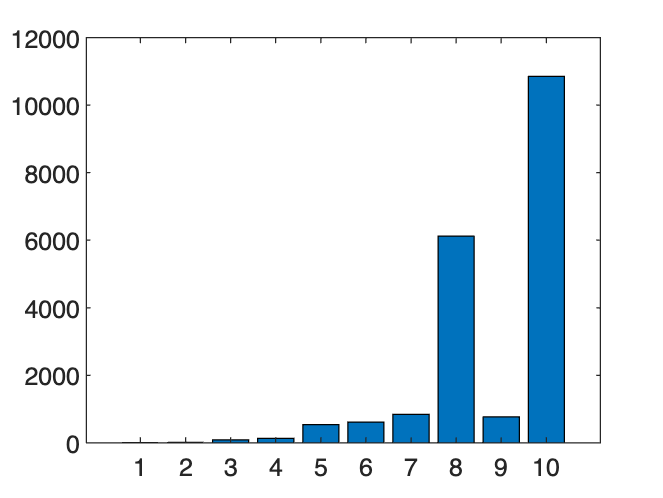

bar(X,V)

Step 1: epoch

function epoch(k)
global N X x_index V cumulative_sum samplesize f_hat

%退火冷却，温度随着迭代降低
T_k = 1/log(10+k); 
L_k = 1 ;

%确定x取值
x = X(x_index);

%邻域（此处选择全集）内随机选择候选参数
z_index = randsample(N,1);
while z_index == x_index
    z_index = randsample(N,1);
end
z = X(z_index);

%抽样
for i = 1:L_k
    cumulative_sum(z_index) =  cumulative_sum(z_index) + simulation(z);
    cumulative_sum(x_index) =  cumulative_sum(x_index) + simulation(x);
end

%记录抽样数量
samplesize(x_index) = samplesize(x_index)+L_k;
samplesize(z_index) = samplesize(z_index)+L_k;

%计算估计值
f_hat = cumulative_sum./samplesize;

%计算接受候选参数的概率
Delta = exp(-max(0,f_hat(z_index)-f_hat(x_index))/T_k);

%更新参数
if rand(1) <= Delta
    x_index = z_index;
end

%纪录访问次数
V(x_index) = V(x_index)+1;

end

仿真过程

function output = simulation(parameter)
    output = - (randn()*parameter + parameter/10);
end

参考文献

Alrefaei, M. H., & Andradóttir, S. (1999). A Simulated Annealing Algorithm with Constant Temperature for Discrete Stochastic Optimization. *Management Science*, *45*(5), 748–764. [https://doi.org/10.1287/mnsc.45.5.748](https://doi.org/10.1287/mnsc.45.5.748)